# Phasors for circuit elements

Review of the electrical elements, in particular the principal passive elements: resistors, inductors and capacitors.

Addition of the phasor representation, definition of impedance, and definition of inductive and capacitive reactance.

## Resistance

Phasor homogeneity property is applied to transform Ohm's law into phasor representation.


$$u_R \left(t\right)=R\;i_R \left(t\right)$$



$$\underline{U} =R\;\underline{\mathrm{I}}$$


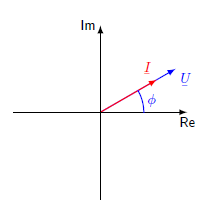

As shown in the phasor diagram, voltage and current are in phase.

## **Inductance**

Phasor differentiation property simplifies the derivative term of Ohm's law in the phasor form.


$$u_L \left(t\right)=L\;\frac{{\textrm{di}}_L \left(t\right)}{\textrm{dt}}$$



$$\underline{U} =j\;\omega \;L\;\underline{I} =j\;X_L \;\underline{I}$$


Whit this transformation a new term is defined: the **inductive reactance**$\;X_L$.

- 
$$X_L \;=\omega \;L\;\left\lbrack \Omega \right\rbrack$$


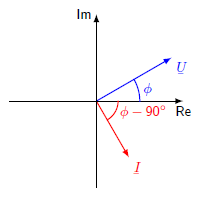

As shown in the phasor diagram, in steady state, inductor current lags inductor voltage by 90º.

Or in other words, in inductive circuits $\phi_U +90º=\phi_I$.

## Capacitance

Phasor integration property simplifies the integrative term of Ohm's law in the phasor form.


$$i_C \left(t\right)=C\;\frac{{\textrm{du}}_C \left(t\right)}{\textrm{dt}}\;\Longrightarrow u_C \left(t\right)=\frac{1}{C}\;\int i_C \left(t\right)\;\textrm{dt}$$
 

$\underline{U} =-j\;\frac{1}{\omega \;C}\;\underline{I} =-j\;X_C \;\underline{I}$    (pay attention to the negative sign!!)

Whit this transformation a new term is defined: the **capacitive reactance**$\;X_C$.

- $X_C \;$= $\frac{1}{\omega \;C}\;\left\lbrack \Omega \right\rbrack$

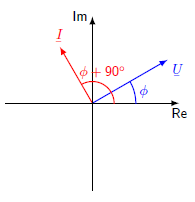

As shown in the phasor diagram, in steady state, capacitor voltage lags capacitor current by 90º.

Or in other words, in capicitive circuits $\phi_U =\phi_I +90º$.

## Impedance

An impedance Z is the complex-valued generalization of a resistance or passive element.

With it, a generalized Ohm's law is defined:

$\underline{U} =\underline{Z} \;\underline{\mathrm{I}}$     or     $\underline{I} =\underline{Y} \;\underline{U}$    

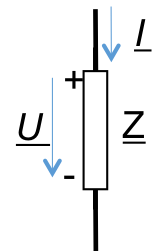  

- Impedance $\underline{Z} =R+j\;X\;\;\left\lbrack \Omega \right\rbrack$, assembles resistance (R) and reactance (X), which can be inductive (positive term) or capacitive (negative term).

- Admittance  $\underline{Y} \equiv \frac{1}{\underline{Z} }=G+j\;B\;\;\left\lbrack \Omega^{-1} \right\rbrack$, defined as the inverse of the impedance, where G is named conductance and B is named susceptance.                  

### Impedance and admittance association

#### Series association 

- 
$$\underline{Z_{\textrm{eq}} } =\underline{Z_1 } +\underline{Z_2 } +\cdots +\underline{Z_N } \;$$


- Current *I* does not change 

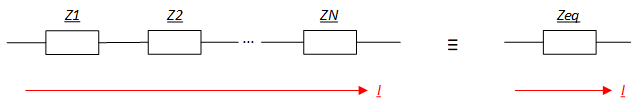

#### Parallel association 

- 
$$\underline{Y_{\textrm{eq}} } =\underline{Y_1 } +\underline{Y_2 } +\cdots +\underline{Y_N } \;\iff \;\underline{Z_{\textrm{eq}} } =\frac{1}{\underline{Z_1 } }+\frac{1}{\underline{Z_2 } }+\cdots +\frac{1}{\underline{Z_N } }$$


- Voltage *V* does not change

- Particular case with only 2 impedances: $\underline{Z_{\textrm{eq}} } =\frac{\underline{Z_1 } \;\underline{Z_2 } }{\underline{Z_1 } +\underline{Z_2 } }$

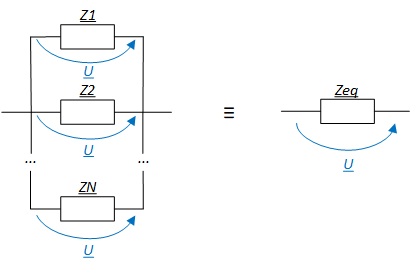

## Exercise 1: Phasor visualization

With the following Matlab commands, plot the phasor diagrams of voltage and current across an impedance.

Use the slider bar to define the impedance, either in polar or rectangular form (uncomment the one you want to use and comment the other one). Try definig the following impedances:

- pure resistive impedance, 

- pure inductive impedance, 

- pure capacitive impedance,

- RL impedance,

- RC impedance.

Verify in each case the impedance, voltage and current phasor representation. 

% Phasor representation of voltage and current across an impedance
close all
clear all
clc

% Definition of frequency (𝜔), time and voltage (magnitude and angle)
omega=2*pi*50

omega = 314.1593

Vrms=230

Vrms = 230

Vang=0

Vang = 0

t=0:0.0001:0.04;

#### Impedance definition - Polar form

% Define magnitude and angle for the polar form:
% Z =6.2;
% Zang = 270;

#### Impedance definition - Rectangular form

% Define real and imaginary part for the rectangular form:
 Zreal =-2;
 Zimag = -5;

 Zcomp=Zreal+1i*Zimag

Zcomp = -2.0000 - 5.0000i

 Z=abs(Zcomp)

Z = 5.3852

 Zang=angle(Zcomp)*180/pi

Zang = -111.8014

#### Impedance phasor

% Phasor exponential form: Xph = Xrms*e^jθ (θ in radians)
Zph=Z*exp(1i*(Zang*pi/180))

Zph = -2.0000 - 5.0000i


% Impedance phasor
figure('Position',[400 200 400 400])
title('Phasor Z')
axis([-Z*1.2,Z*1.2 -Z*1.2,Z*1.2])
hold all
line([0,real(Zph)],[0,imag(Zph)],'Color','K')
circle1=Z*exp(1i*(2*pi*50*t))

circle1 =    5.3852 + 0.0000i   5.3825 + 0.1692i   5.3745 + 0.3381i   5.3613 + 0.5068i   5.3427 + 0.6749i   5.3189 + 0.8424i   5.2898 + 1.0091i   5.2555 + 1.1747i   5.2160 + 1.3392i   5.1713 + 1.5024i   5.1216 + 1.6641i   5.0668 + 1.8242i   5.0070 + 1.9824i   4.9423 + 2.1387i   4.8726 + 2.2929i   4.7982 + 2.4448i   4.7191 + 2.5943i   4.6352 + 2.7413i   4.5468 + 2.8855i   4.4540 + 3.0269i   4.3567 + 3.1653i   4.2551 + 3.3006i   4.1493 + 3.4326i   4.0395 + 3.5613i   3.9256 + 3.6864i   3.8079 + 3.8079i   3.6864 + 3.9256i   3.5613 + 4.0395i   3.4326 + 4.1493i   3.3006 + 4.2551i   3.1653 + 4.3567i   3.0269 + 4.4540i   2.8855 + 4.5468i   2.7413 + 4.6352i   2.5943 + 4.7191i   2.4448 + 4.7982i   2.2929 + 4.8726i   2.1387 + 4.9423i   1.9824 + 5.0070i   1.8242 + 5.0668i   1.6641 + 5.1216i   1.5024 + 5.1713i   1.3392 + 5.2160i   1.1747 + 5.2555i   1.0091 + 5.2898i   0.8424 + 5.3189i   0.6749 + 5.3427i   0.5068 + 5.3613i   0.3381 + 5.3745i   0.1692 + 5.3825i


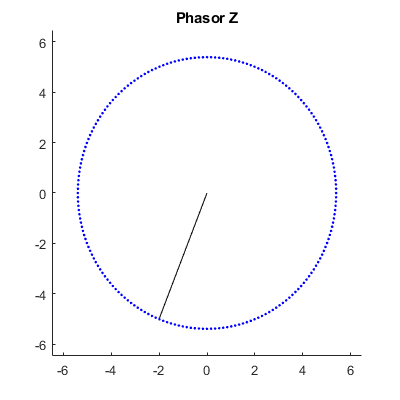

plot(circle1,'.','Color','b')

#### Voltage and Current phasors

% Phasor exponential form: Xph = Xrms*e^jθ (θ in radians)
Vph=Vrms*exp(1i*(Vang*pi/180))

Vph = 230


% Current I calculation, phasor, magnitude and angle
Iph=Vph/Zph

Iph = -15.8621 + 39.6552i

Irms=abs(Iph)

Irms = 42.7099

Iang=angle(Iph)*180/pi

Iang = 111.8014


% Current-Voltage phasor
figure('Position',[400 200 400 400])
title('Voltage and Current Phasors')
axis([-Vrms*1.2,Vrms*1.2 -Vrms*1.2,Vrms*1.2])
line([0,real(Vph)],[0,imag(Vph)],'Color','r')
hold all
line([0,real(Iph)],[0,imag(Iph)],'Color','g')
circle=Vrms*exp(1i*(2*pi*50*t))

circle = 	1.0e+02 *

   2.3000 + 0.0000i   2.2989 + 0.0722i   2.2955 + 0.1444i   2.2898 + 0.2164i   2.2819 + 0.2883i   2.2717 + 0.3598i   2.2593 + 0.4310i   2.2446 + 0.5017i   2.2277 + 0.5720i   2.2087 + 0.6417i   2.1874 + 0.7107i   2.1640 + 0.7791i   2.1385 + 0.8467i   2.1108 + 0.9134i   2.0811 + 0.9793i   2.0493 + 1.0442i   2.0155 + 1.1080i   1.9797 + 1.1708i   1.9420 + 1.2324i   1.9023 + 1.2928i   1.8607 + 1.3519i   1.8174 + 1.4097i   1.7722 + 1.4661i   1.7253 + 1.5210i   1.6766 + 1.5745i   1.6263 + 1.6263i   1.5745 + 1.6766i   1.5210 + 1.7253i   1.4661 + 1.7722i   1.4097 + 1.8174i   1.3519 + 1.8607i   1.2928 + 1.9023i   1.2324 + 1.9420i   1.1708 + 1.9797i   1.1080 + 2.0155i   1.0442 + 2.0493i   0.9793 + 2.0811i   0.9134 + 2.1108i   0.8467 + 2.1385i   0.7791 + 2.1640i   0.7107 + 2.1874i   0.6417 + 2.2087i   0.5720 + 2.2277i   0.5017 + 2.2446i   0.4310 + 2.2593i   0.3598 + 2.2717i   0.2883 + 2.2819i   0.2164 + 2.2898i   0.1444 + 2.2955i   0.0722 + 2.2989i


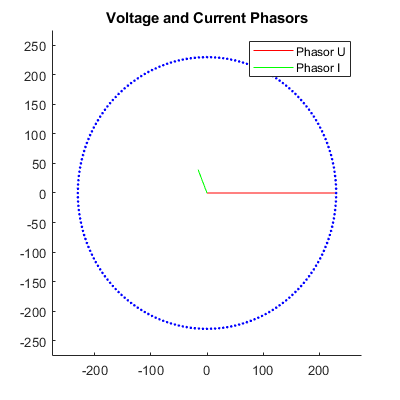

plot(circle,'.','Color','b')
legend('Phasor U','Phasor I')

Solution:

- pure resistive impedance: only real part (or Zang=0º),

- pure inductive impedance: only imaginary positive part (or Zang=90º),

- pure capacitive impedance: only imaginary negative part (or Zang=270º),

- RL impedance: real and imaginary positive part,

- RC impedance: real and imaginary negative part.

Observation:

It was mentioned above that, in steady state, when having pure inductive and pure capacitive impedances, inductor current lags inductor voltage by 90º, and capacitor voltage lags capacitor current by 90º, respectively.

As observed in the phasor representation, with RLC circuits, the addition of the resistance modifies this phase difference. However, if the resulting reactance is:

- inductive, inductor current lags inductor voltage still. I.e., $\phi_U >\phi_I$.

- capacitive, capacitor voltage lags capacitor current still. I.e., $\phi_U <\phi_I$.

## Exercise 2: Series - Parallel association

Find the current accross *Z1* using series and parallel association rules for impedances, instead of using Kirchhoff's mesh laws, if *U* = 240V.

close all
clear all

% Parameters:
U=240; Z1=2; Z2=4; Z3=6; Z4=6; Z5=4; Z6=4; Z7=2; Z8=12; Z9=8; Z10=4; % values in SI

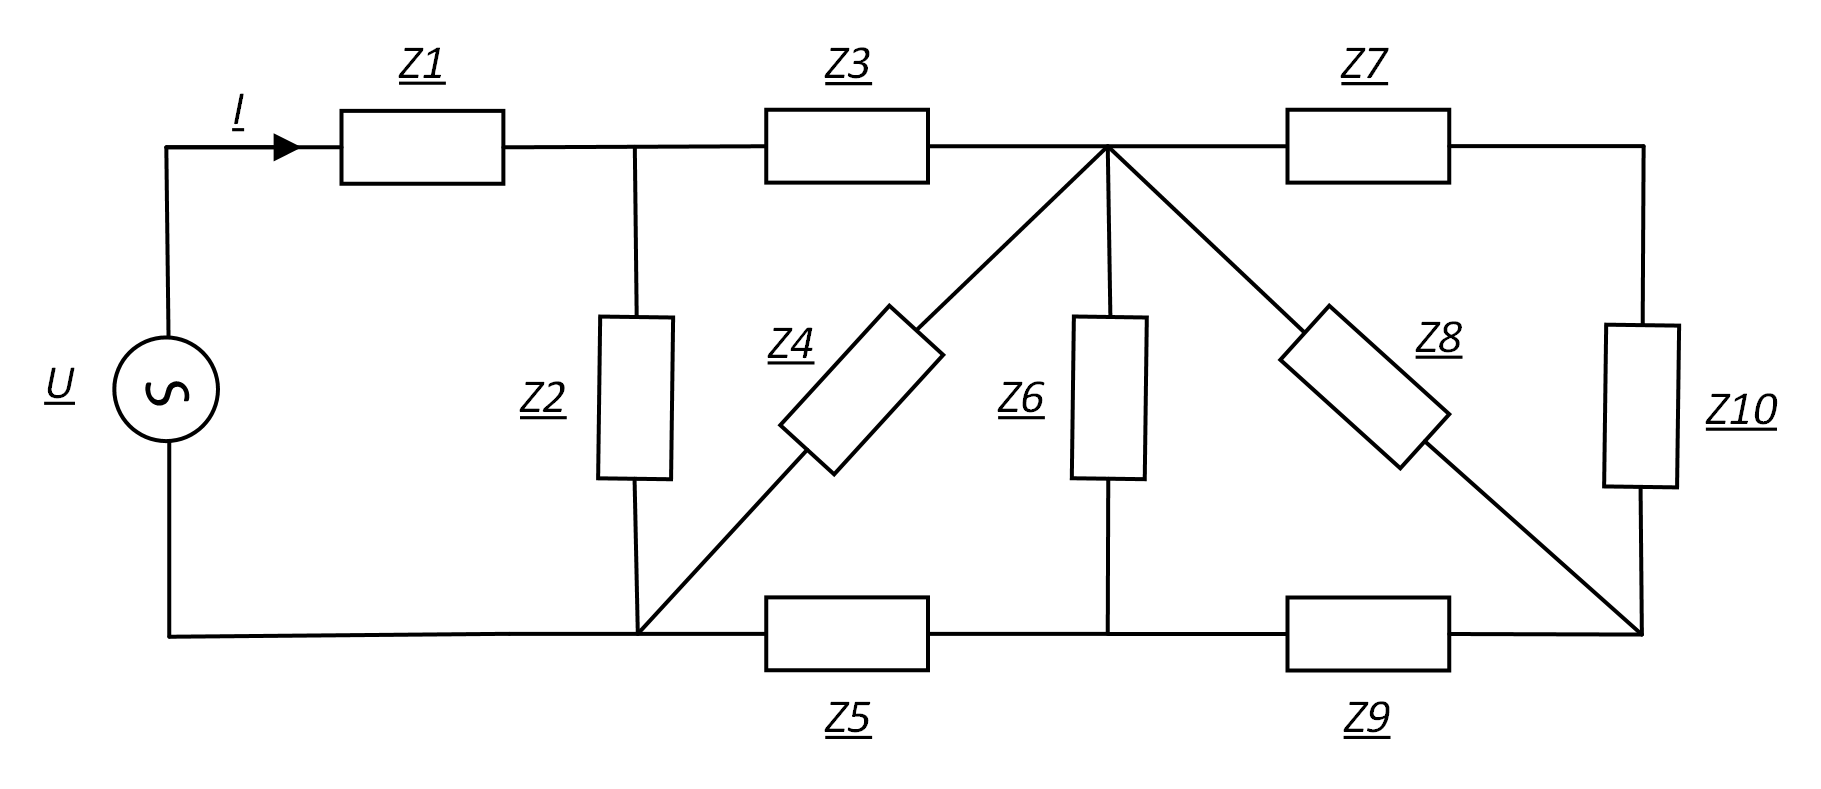

**Solution:**

*I* = 50,1A

**Resolution:**

When the circuit looks complicated, re-drawing the circuit can help us detect the series and parallel associations. If we start from the right hand side, we find that impedances Z7 and Z10 are in series, and these together are in parallel with Z8 as shown below.

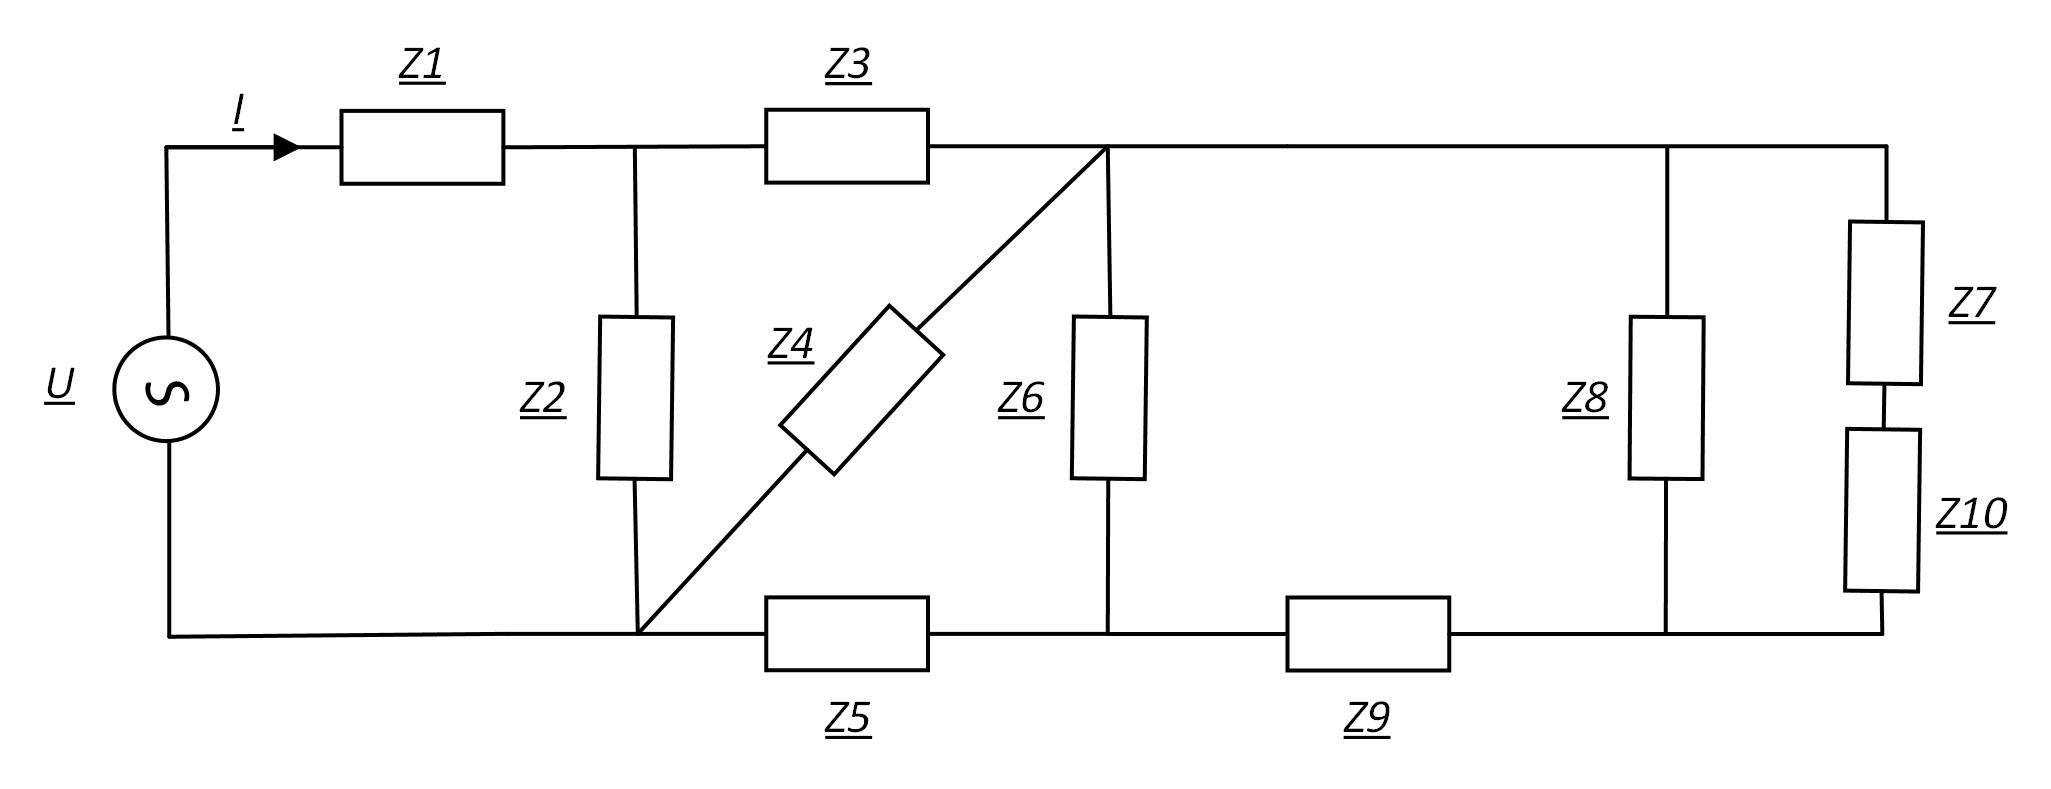

With this re-configuration, it is easier to appreciate again that the equivalent ensemble of  Z7, Z8 and Z10 (Z7108) is in series with Z9, and these together are in parallel with Z6. 

The idea is to keep on going, until finding the gloal equivalent impedance Zeq.

Z710 = Z7+Z10

Z710 = 6

Z7108 = (Z710*Z8)/(Z710+Z8) % we use the particular case with only 2 impedances in parallel

Z7108 = 4

Z71089 = Z7108+Z9

Z71089 = 12

Z710896 = (Z71089*Z6)/(Z71089+Z6)

Z710896 = 3

Z7108965 = Z710896+Z5

Z7108965 = 7

Z71089654 = (Z7108965*Z4)/(Z7108965+Z4)

Z71089654 = 3.2308

Z710896543 = Z71089654+Z3

Z710896543 = 9.2308

Z7108965432 = (Z710896543*Z2)/(Z710896543+Z2)

Z7108965432 = 2.7907

Z71089654321 = Z7108965432+Z1

Z71089654321 = 4.7907

Zeq = Z71089654321

Zeq = 4.7907

% I calculation:
I = U/Zeq

I = 50.0971

## Exercise 3: Series - Parallel association

Find the equivalent impedance of the following RLC circuit, if the circuit frequency is 50Hz.

close all
clear all

% Parameters:
R1=2; R2=4; R3=1; R4=5; L1=0.1; L2=0.2; C1=1; C2=2;     % values in SI

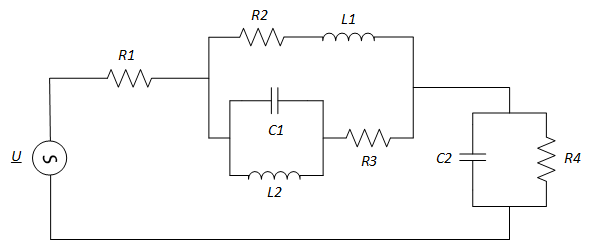

Note: Bear in mind that an impedance assembles resistance and reactance (inductive or capacitive), not the inductance o capacitance of the inductor or capacitor, respictively.

**Solution:**


$$\underline{Z_{\textrm{eq}} } =3+j\;0\ldotp 26\;\left\lbrack \Omega \right\rbrack$$


**Resolution:**

We first calculate the reactances XL and Xc. Hence, we need to know the angular frequency, which we can obtain from the frequency.

f=50    % frequency

f = 50

omega=2*pi*f; % angular frequency
XL1=omega*L1

XL1 = 31.4159

XL2=omega*L2

XL2 = 62.8319

XC1=1/(C1*omega)

XC1 = 0.0032

XC2=1/(C2*omega)

XC2 = 0.0016

We can proceed with the calculation of the equivalent impedance Zeq:

Zeq=R1+((R2+i*XL1)*((-i*XC1*i*XL2/(-i*XC1+i*XL2))+R3)/((R2+i*XL1)+((-i*XC1*i*XL2/(-i*XC1+i*XL2))+R3)))+(-i*XC2*R4/(-i*XC2+R4))

Zeq = 2.9953 + 0.0263i

## Exercise 4: AC circuits using phasors

Find the voltage across the resistor, $u_o \left(t\right)$, in steady-state, if:


$$u_i \left(t\right)=5\;\cos \left(4t+\frac{\pi }{4}\right)\left\lbrack V\right\rbrack$$


close all
clear all

% Parameters:
R=1; L=0.1; C=2; % values in SI

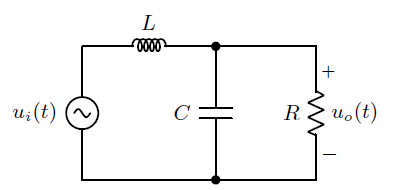

Observation:

This exercise is a clear example of how circuit analysis becomes easier when using phasors. Otherwise we would have a second order differential equation to solve (ODE).

**Solution:**


$$u_o \left(t\right)=2\ldotp 24\;\cos \left(4t-2\ldotp 17\right)\left\lbrack V\right\rbrack$$


**Resolution:**

We first calculate the reactances XL and Xc. Hence, we need to know the angular frequency, which we can obtain from the voltage AC signal.

omega=4; % angular frequency
XL=omega*L

XL = 0.4000

XC=1/(C*omega)

XC = 0.1250

We will be operating with phasors, so we transform into phasor form the voltage signal $u_i \left(t\right)$.

% Polar form
Ui=5/sqrt(2)    % Urms

Ui = 3.5355

Uiang=45        % in degrees

Uiang = 45

% Rectangular form
Uireal=Ui*cos(Uiang*pi/180);
Uiimag=Ui*sin(Uiang*pi/180);
Uicomp=Uireal+i*Uiimag;
% Exponential form: Uph = Urms*e^jθ (θ in radians)
Uiph=Ui*exp(1i*(Uiang*pi/180)) 

Uiph = 2.5000 + 2.5000i

Circuit analysis

The voltage across the resistor, $u_o \left(t\right)$, is the same one for the capacitor. Hence, analyzing the mesh on the left we obtain: 


$$\underline{U_I } =\underline{U_O } +\underline{I} \;jX_L$$


We need to know the current across the inductor, which is the same one for the entire equivalent impedance:


$$\underline{U_I } =\underline{I} \;\underline{Z_{\textrm{eq}} } \;$$


We calculate then the equivalent impedance Zeq, the current I, and finally the voltage Uo.

% Rectangular form
Zeq=i*XL+((R*-i*XC)/(R+(-i*XC)))   % L in series with R and C in parallel 

Zeq = 0.0154 + 0.2769i

% Polar form
Z=abs(Zeq)

Z = 0.2774

Zang=angle(Zeq)*180/pi

Zang = 86.8202

% Exponential form
Zph=Z*exp(1i*(Zang*pi/180))    

Zph = 0.0154 + 0.2769i


% Current phasor
Iph=Uiph/Zph

Iph = 9.5000 - 8.5000i


% Voltage Uo phasor
Uoph=Uiph-(Iph*i*XL)

Uoph = -0.9000 - 1.3000i

Uo=abs(Uoph)    % RMS value

Uo = 1.5811

Uoang=angle(Uoph)*180/pi

Uoang = -124.6952

amplitude=Uo*sqrt(2)    

amplitude = 2.2361

phase=Uoang*pi/180

phase = -2.1763

We end up transforming the voltage phasor into a time domain signal, with its amplitude and phase, and same angular frequency.


$$u_o \left(t\right)=2\ldotp 24\;\cos \left(4t-2\ldotp 17\right)\left\lbrack V\right\rbrack$$


Observation: 

Comparison between the time response of the resistor voltage of the RLC circuit and the calculated steady-state voltage.

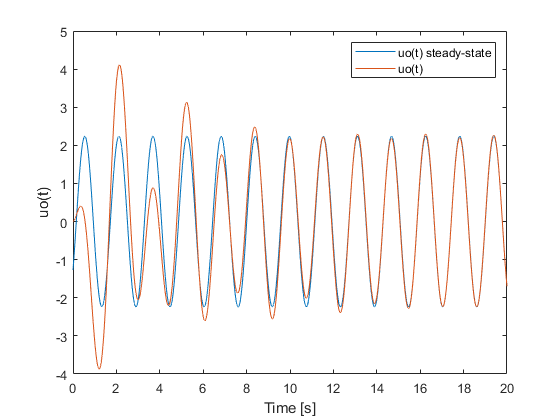

t=0:0.001:20;
% Time response voltage RLC circuit
ut=(1.273*cos(2.22*t)-3.166*sin(2.22*t)).*exp(-t/4)+2.24*cos(4*t-2.17);

% Steady-state voltage
v_t=Uo*sqrt(2)*cos(omega*t+Uoang*pi/180);

title('RLC circuit: Time response vs Steady-state')
plot(t,v_t)
hold all
plot(t,ut)
legend('uo(t) steady-state','uo(t)')
xlabel('Time [s]')
ylabel('uo(t)')